% Exercise 1 data generation (genGauss function)
% Generate 1000 samples for each class


muA = [0; 4; 7];
SigmaA = [4 -6 8;
          -6 12 -9;
          8 -9 20];

muB = [3; 9; -1];
SigmaB = [3.0184  0.4331 -1.4481;
    0.4331  0.9436 -0.6456;
    -1.4481 -0.6456  1.2880];

muC = [2; 1; 3];
SigmaC = [6.8928 -1.3750  3.1945;
    -1.3750  3.3572  0.6945;
    3.1945  0.6945  3.7500];

muD = [-1; 8; 12];
SigmaD = [6.8928 -1.3750  3.1945;
    -1.3750  3.3572  0.6945;
    3.1945  0.6945  3.7500];

muE = [-3; 10; 9];
SigmaE = [6.8928 -1.3750  3.1945;
    -1.3750  3.3572  0.6945;
    3.1945  0.6945  3.7500];

X_a = genGauss(750000, muA, SigmaA);  % K×3
X_b = genGauss(190000, muB, SigmaB);
X_c = genGauss(45000, muC, SigmaC);
X_d = genGauss(12000, muD, SigmaD);
X_e = genGauss(3000, muE, SigmaE);

% Stack into input matrix: each COLUMN is one sample
X = [X_a; X_b; X_c; X_d; X_e]';   % 3 × 3000


labels = [ones(750000,1)*1; ones(190000,1)*2; ones(45000,1)*3; ones(12000,1)*4; ones(3000,1)*5];

indices=randperm(1000000);

train_indices = indices(1:100000);
test_indices = indices(100001:end);

length(train_indices)

ans = 100000

length(test_indices)

ans = 900000


train_X = X(:, train_indices)

train_X =     3.6507   -0.9868    1.4282    0.4443    5.6098   -1.4015    2.5453   -0.0954    2.0041   -1.8323    3.4751    3.2708   -4.4567   -0.8437   -2.6359    0.0899    1.3271   -0.2713    4.1232   -1.7320    2.2789    2.1110   -0.2168    1.3721    3.1032    0.7397   -1.9923   -1.7964    1.1940    4.8183   -0.0111    3.5524    2.3632    3.7265    0.5182    1.1553    2.9427    0.8103    3.2510    1.2955   -2.2969    3.1146    3.8662    0.9604    0.6811    2.3416   -2.0676    5.8868    3.2004    5.8269
    8.5290    2.2295    0.9861    3.9861    9.2090    2.2883    8.5120    5.9947    2.3112    6.3873   -0.1793   10.5745   12.1823    4.6838    6.4141    2.5396   -1.6431    3.1534    9.4055    7.4820    7.5655    2.4198    5.4956    8.2901    3.1662    8.5180    6.9200    7.2573    3.7379   -7.2669    2.8466   -0.6624    1.0995   -0.4564    2.5122    4.2864   10.1115    1.0360    9.0376   -0.3144   10.0903    9.0354   -1.1512    7.8431    2.8387   -1.8915    6.0805   -2.5762   -2.489

test_X = X(:, test_indices)

test_X =     3.1370    0.4232    2.8352    1.5251    1.1058    0.6166    0.5628    1.9835   -0.7864    1.6132    0.8536    2.9636    2.3642   -0.0978    0.4341   -2.6550    2.1720   -0.3248    1.0522    2.5094   -0.9702    3.4404   -2.2594   -0.4252    0.1080    2.8570   -0.6695    2.0016   -1.9374    2.4247    1.2137   -1.1614    0.1881    0.4931    2.6963   -2.7326   -0.6944   -0.9183    4.1916   -0.1044    3.2058   -0.6678    0.8183    1.3669    2.9881   -2.2799    0.2002   -0.0617    2.4241   -2.4357
   10.0760    5.9656    0.9476    4.7736   -0.1526    1.0316    0.4884    3.6003    4.5643    9.2415    1.3624    3.0704    8.8547    9.0072    4.0725    8.2871    2.5230    4.8496    2.8622   10.1475    8.2191   -0.4479    8.1562    7.6067    3.5876   -0.8987    5.3871    2.0547    5.9123    2.7940    7.5823    5.5084    3.9052    3.0882    7.7067   11.4971    7.5731    4.6311    9.9686    3.9461    1.0531    6.4577    0.6745    0.6963   -0.8273    9.0122    4.6541    6.3875    1.9231

train_labels = labels(train_indices);
test_labels = labels(test_indices);

num_A_samples = sum(train_labels == 1)

num_A_samples = 74951

num_B_samples = sum(train_labels == 2)

num_B_samples = 19023

num_C_samples = sum(train_labels == 3)

num_C_samples = 4479

num_D_samples = sum(train_labels == 4)

num_D_samples = 1257

num_E_samples = sum(train_labels == 5)

num_E_samples = 290

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 10-Jun-2026 00:14:03
%
% This script assumes these variables are defined:
%
%   X - input data.
%   T - target data.

inputs = train_X;
T = ind2vec(labels');
size(T)

ans =            5     1000000


train_T = T(:, train_indices);
targets = train_T;

size(inputs)

ans =            3      100000


size(targets)

ans =            5      100000


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.
Cannot perform computations on a GPU.
Parallel Computing Toolbox license is not available.


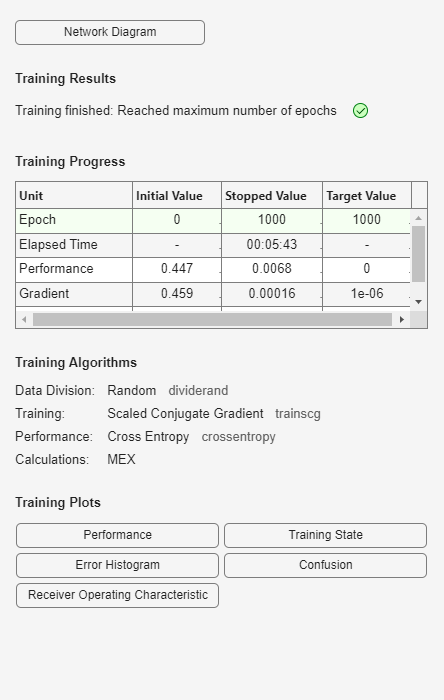


% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 100/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 0/100;

% Train the Network
[net,tr] = train(net,inputs,targets, 'UseParallel', 'yes','UseGPU','yes');

y = net(inputs);
e = gsubtract(targets,y);
performance = perform(net,targets,y)

performance = 0.0068

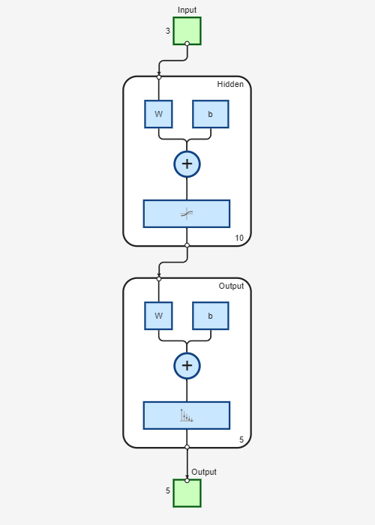

tind = vec2ind(targets);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)

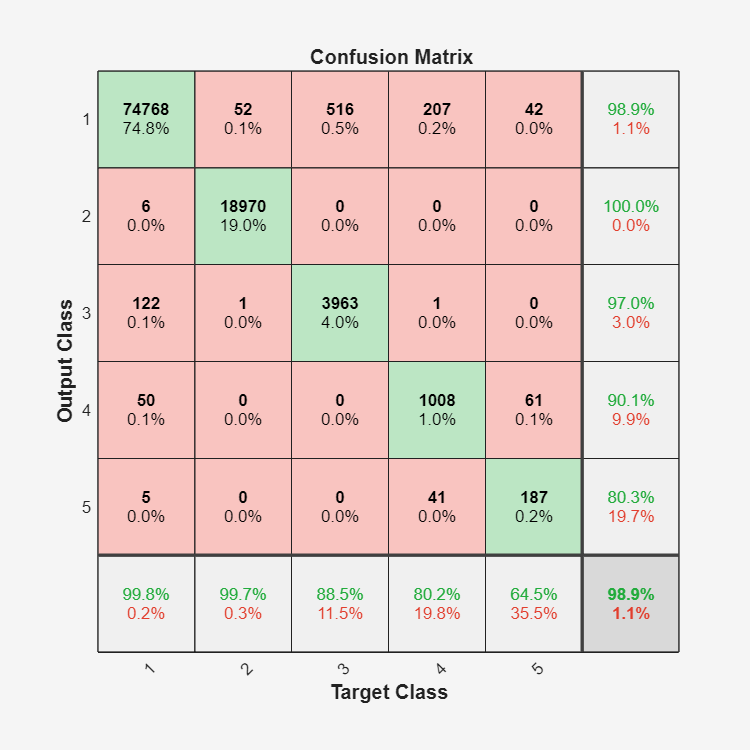


% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(targets,y)

%figure, plotroc(t,y)

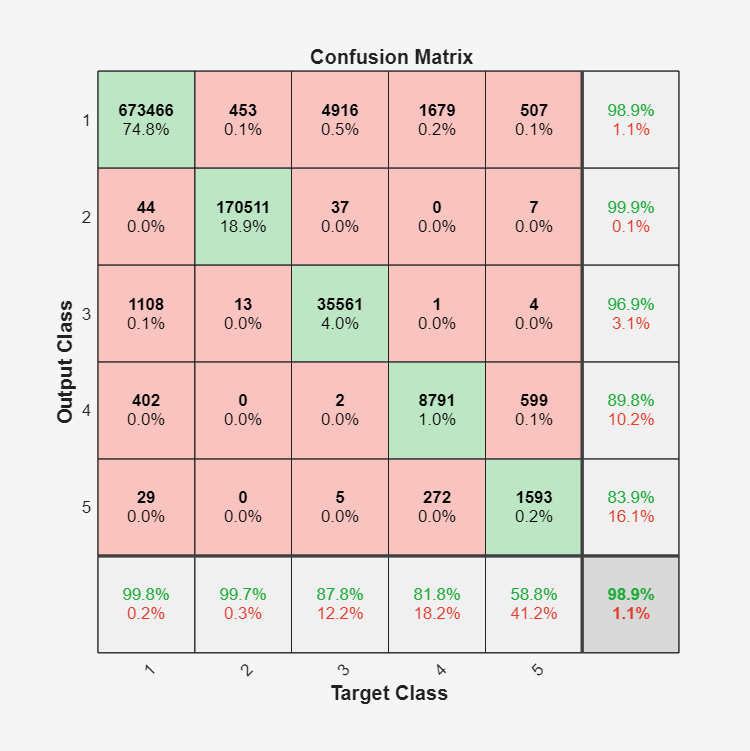

test_y = net(test_X);
test_T = T(:, test_indices);
plotconfusion(test_T, test_y)

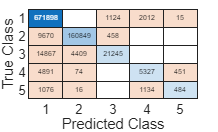

model = fitcdiscr(train_X', train_labels);
predicted_labels = predict(model, test_X');
figure;
confusionchart(test_labels, predicted_labels)